%-----------------------------------
%初始化
%nPoint：采样点数
%z0：设定的距离
%sigma：波数
%色散相位：-4*pi*((b0+z0)+b1*sigma).*sigma;
%-----------------------------------
nPoint = 2^18;
z0 = 10;
b0 = 5;
b1 = 0;
sigma = -(nPoint/2)*(3.25/1024):(3.25/1024):(nPoint/2-1)*(3.25/1024);
%加窗 window1
window1 = ones(1,1024);
fSigma = fitfSigma(sigma);
pSigma=-4*pi*((b0+z0)+b1*sigma).*sigma;
[min1,indexmin]= min(pSigma);
pSigma=-4*pi*((b0+z0)+b1*(sigma+sigma(indexmin))).*(sigma+sigma(indexmin));%+sigma(indexmin)
%-----------------------------------
%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
powerTotal = 0;
for n=1:1:length(fSigma)
    powerTotal=powerTotal+fSigma(n);
end
p = 0;
for n=1:1:nPoint
    p = p+ fSigma(n)*sigma(n);
end
lambdaA = powerTotal/p;
fSigma = fitfSigma(sigma+1/lambdaA);
pSigma=-4*pi*((b0+z0)+b1*(sigma+sigma(indexmin)).*(sigma+sigma(indexmin)));
fSigma = sigmult(fSigma,-2^17:2^17-1,window1,-2^9:2^9-1);
pSigma = sigmult(pSigma,-2^17:2^17-1,window1,-2^9:2^9-1);
iSigma = fSigma.*exp(1i*pSigma);
disp("光谱")

光谱


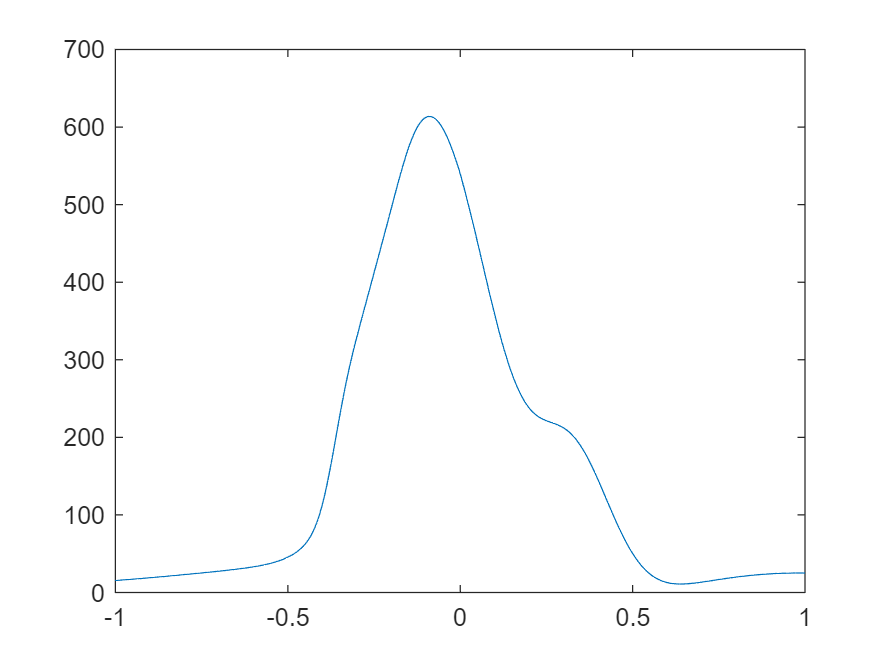

plot(sigma,fSigma);
xlim([-1 1]);

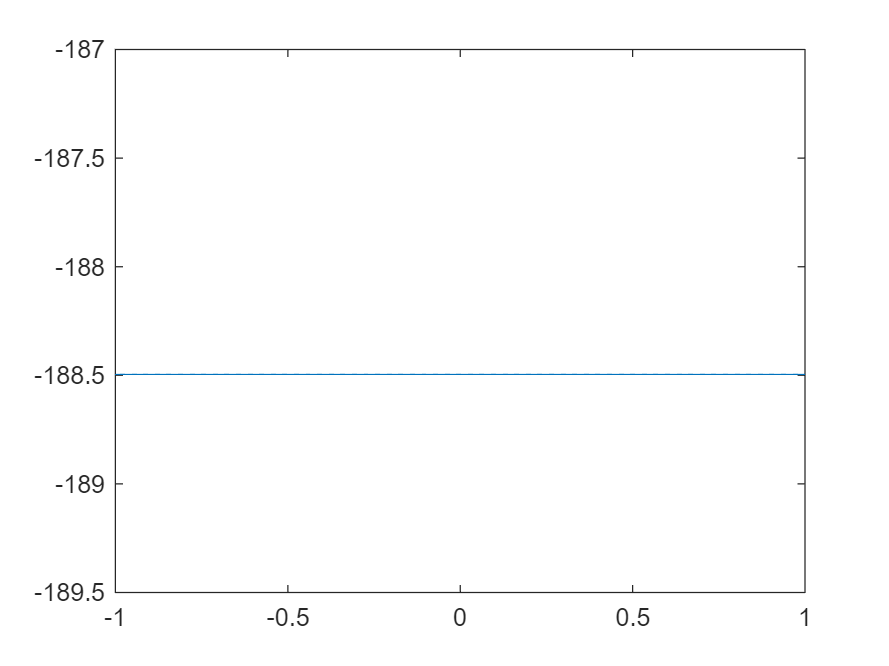

plot(sigma,pSigma);
xlim([-1 1]);


deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = ((-nPoint/2):(nPoint/2-1))*deltaZ;

ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase = (angle(ifftIsigma));
intensityhalf = intensity(1:nPoint/2);
intensity(1:nPoint/2)=intensity(nPoint/2+1:nPoint);
intensity(nPoint/2+1:nPoint) = intensityhalf;
phasehalf = phase(1:nPoint/2);
phase(1:nPoint/2)=phase(nPoint/2+1:nPoint);
phase(nPoint/2+1:nPoint) = phasehalf;
[max1,index]= max(intensity);
za1=zData(index)

za1 = 0

phase(index)

ans = 2.1559e-14

disp("未作最小二乘的FFT后的振幅分布")

未作最小二乘的FFT后的振幅分布


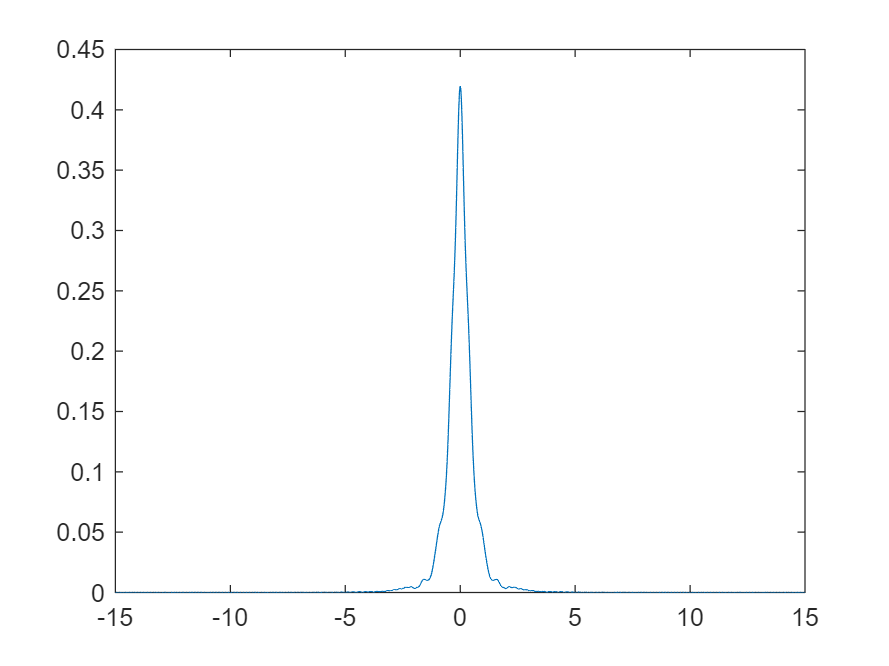

plot(zData,intensity);
xlim([zData(index)-15 zData(index)+15]);

disp("未作最小二乘的FFT后的相位分布")

未作最小二乘的FFT后的相位分布


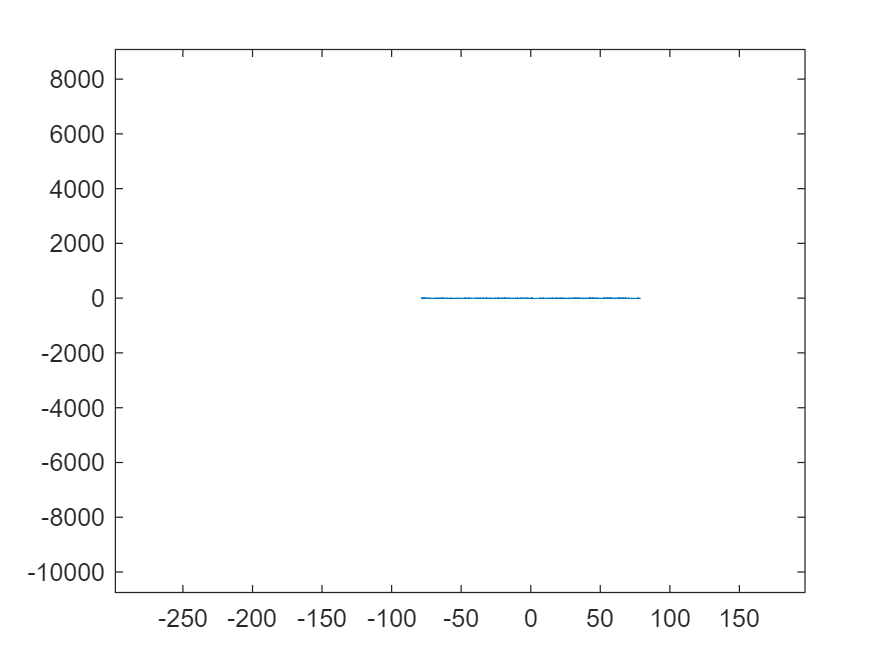

plot(zData,phase);
xlim([zData(index)-0.1 zData(index)+0.1]);

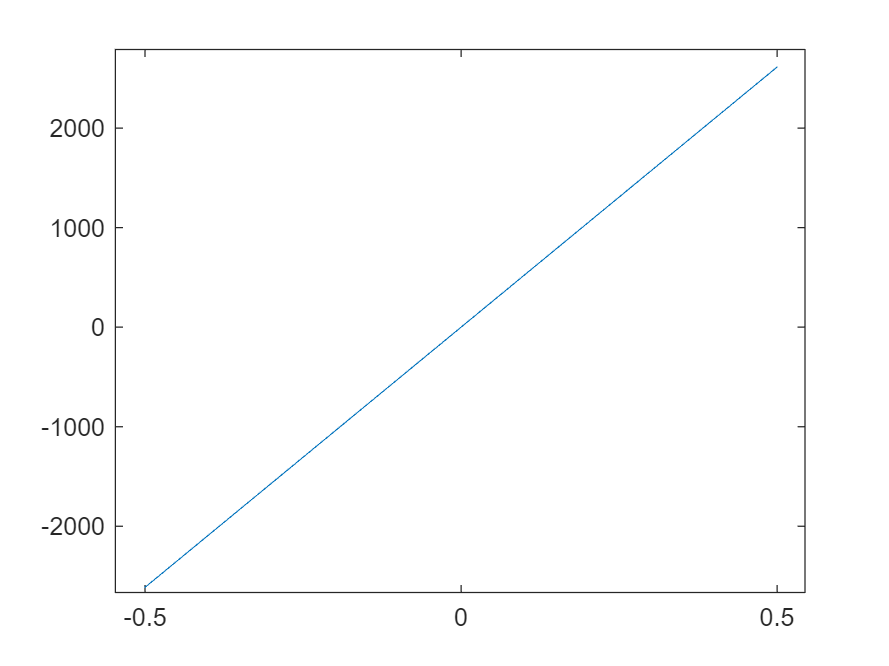


unwrapZend = zData(abs(zData-(za1+0.5))<0.001);
unwrapZ_1 = zData(abs(zData-(za1-0.5))<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = index;
unwrapNe = find(zData==unwrapZend(end));
unwrapN_1 = find(zData==unwrapZ_1(1));
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));


phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N

zp1 = -4.1200e-18

za1

za1 = 0

function fSigma = fitfSigma(x)
%Coefficients (with 95% confidence bounds):
       a1 =       88.19  ;%(51.68, 124.7)
       b1 =       1.378  ;%(1.347, 1.409)
       c1 =      0.1243  ;%(0.0879, 0.1606)
       a2 =      0.9322  ;%(-1.209, 3.073)
       b2 =       1.542  ;%(1.518, 1.565)
       c2 =     0.01341  ;%(-0.02512, 0.05195)
       a3 =       69.18  ;%(-6.223, 144.6)
       b3 =        1.27  ;%(1.228, 1.312)
       c3 =     0.07202  ;%(0.03205, 0.112)
       a4 =       528.7  ;%(493.5, 563.8)
       b4 =       1.488  ;%(1.483, 1.494)
       c4 =      0.2199  ;%(0.2153, 0.2245)
       a5 =       62.39  ;%(-14.96, 139.7)
       b5 =       1.207  ;%(1.188, 1.225)
       c5 =     0.05735  ;%(0.04772, 0.06698)
       a6 =         181  ;%(163.3, 198.6)
       b6 =        1.87  ;%(1.867, 1.873)
       c6 =       0.158  ;%(0.153, 0.1629)
       a7 =      -60.41  ;%(-80.21, -40.6)
       b7 =        1.92  ;%(1.789, 2.051)
       c7 =      0.4102  ;%(0.3363, 0.4841)
       a8 =       57.07  ;%(54.59, 59.55)
       b8 =       1.735  ;%(1.728, 1.742)
       c8 =       1.039  ;%(1.023, 1.054)
     fSigma = a1*exp(-((x-b1)/c1).^2) + a2*exp(-((x-b2)/c2).^2) +... 
              a3*exp(-((x-b3)/c3).^2) + a4*exp(-((x-b4)/c4).^2) + ...
              a5*exp(-((x-b5)/c5).^2) + a6*exp(-((x-b6)/c6).^2) + ...
              a7*exp(-((x-b7)/c7).^2) + a8*exp(-((x-b8)/c8).^2);
end